clear all

## Symbolic calculation of G(s)


syms a1 a2 a3 a4...
     A1 A2 A3 A4...
     g1 g2 k1 k2 g...
     h10 h20 h30 h40...
     s lambda_mp lambda_np
A = [ -a1/A1*sqrt( (g/(2*h10)) ), 0, a3/A1*sqrt( (g/(2*h30)) ), 0;...
         0, -a2/A2*sqrt( (g/(2*h20)) ), 0, a4/A2*sqrt( (g/(2*h40)) );...
         0, 0, -a3/A3*sqrt( (g/(2*h30)) ), 0;...
         0, 0, 0, -a4/A4*sqrt( (g/(2*h40)) ) ]

$$A = \begin{array}{l} \left(\begin{array}{cccc} -\frac{a_{1}\,\sqrt{\frac{g}{2\,h_{10}}}}{A_{1}} & 0 & \frac{\sigma_{2}}{A_{1}} & 0\\ 0 & -\frac{a_{2}\,\sqrt{\frac{g}{2\,h_{20}}}}{A_{2}} & 0 & \frac{\sigma_{1}}{A_{2}}\\ 0 & 0 & -\frac{\sigma_{2}}{A_{3}} & 0\\ 0 & 0 & 0 & -\frac{\sigma_{1}}{A_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\sqrt{\frac{g}{2\,h_{40}}}\\ \sigma_{2}=a_{3}\,\sqrt{\frac{g}{2\,h_{30}}} \end{array}$$

B = [ (g1*k1)/A1, 0;...   
         0, (g2*k2)/A2;...
         0, ((1-g2)*k2)/A3;...
         ((1-g1)*k1)/A4, 0 ]

$$B = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}}{A_{1}} & 0\\ 0 & \frac{g_{2}\,k_{2}}{A_{2}}\\ 0 & -\frac{k_{2}\,\left(g_{2}-1\right)}{A_{3}}\\ -\frac{k_{1}\,\left(g_{1}-1\right)}{A_{4}} & 0 \end{array}\right)$$

C = [1, 0, 0, 0; 0, 1, 0, 0]

C =      1     0     0     0
     0     1     0     0


G = C*inv(s*eye(length(A)) - A)*B

$$G = \begin{array}{l} \left(\begin{array}{cc} \frac{g_{1}\,k_{1}}{\sigma_{2}} & -\frac{a_{3}\,k_{2}\,\left(g_{2}-1\right)\,\sqrt{\frac{g}{2\,h_{30}}}}{\sigma_{2}\,\left(A_{3}\,s+a_{3}\,\sqrt{\frac{g}{2\,h_{30}}}\right)}\\ -\frac{a_{4}\,k_{1}\,\left(g_{1}-1\right)\,\sqrt{\frac{g}{2\,h_{40}}}}{\sigma_{1}\,\left(A_{4}\,s+a_{4}\,\sqrt{\frac{g}{2\,h_{40}}}\right)} & \frac{g_{2}\,k_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{2}\,s+a_{2}\,\sqrt{\frac{g}{2\,h_{20}}}\\ \sigma_{2}=A_{1}\,s+a_{1}\,\sqrt{\frac{g}{2\,h_{10}}} \end{array}$$

## Static RGA

s = 0;
G_0 = subs(G)

$$G\_0 = \left(\begin{array}{cc} \frac{g_{1}\,k_{1}}{a_{1}\,\sqrt{\frac{g}{2\,h_{10}}}} & -\frac{k_{2}\,\left(g_{2}-1\right)}{a_{1}\,\sqrt{\frac{g}{2\,h_{10}}}}\\ -\frac{k_{1}\,\left(g_{1}-1\right)}{a_{2}\,\sqrt{\frac{g}{2\,h_{20}}}} & \frac{g_{2}\,k_{2}}{a_{2}\,\sqrt{\frac{g}{2\,h_{20}}}} \end{array}\right)$$

G_0_latex = latex(G_0);

lambda = 1 / ( 1- (G_0(1,2)*G_0(2,1))/(G_0(1,1)*G_0(2,2)) )

$$lambda = -\frac{1}{\frac{\left(g_{1}-1\right)\,\left(g_{2}-1\right)}{g_{1}\,g_{2}}-1}$$

lambda = simplify(lambda)

$$lambda = \frac{g_{1}\,g_{2}}{g_{1}+g_{2}-1}$$

RGA_0 = [lambda, 1-lambda; 1-lambda, lambda];
%Mimimum phase:
par(1) = struct('h10',12.1,'h20',12.6,'h30',2.5,'h40',2.49,'v10',2.99,'v20',2.97,'k1',3.33, 'k2', 3.35, 'g1',0.6,'g2',0.5);
g1 = par(1).g1;
g2 = par(1).g2;
RGA_0_mp = subs(RGA_0)

$$RGA\_0\_mp = \left(\begin{array}{cc} 3 & -2\\ -2 & 3 \end{array}\right)$$

%Mimimum phase:
par(2) = struct('h10',6.79,'h20',8.78,'h30',2.97,'h40',4.17,'v10',2.53,'v20',2.35,'k1',3.14, 'k2', 3.29, 'g1',0.35,'g2',0.3);
g1 = par(2).g1;
g2 = par(2).g2;
RGA_0_np = subs(RGA_0)

$$RGA\_0\_np = \left(\begin{array}{cc} -\frac{3}{10} & \frac{13}{10}\\ \frac{13}{10} & -\frac{3}{10} \end{array}\right)$$

##  dynamic RGA

%Minimum phase
run("quadtank_minphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          12.1      dx:     -2.97e-08 (0)
(2.) nlQuadtank/h2_state
      x:          12.6      dx:     -5.19e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.51      dx:      1.02e-07 (0)
(4.) nlQuadtank/h4_state1
      x:          2.48      dx:      9.35e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

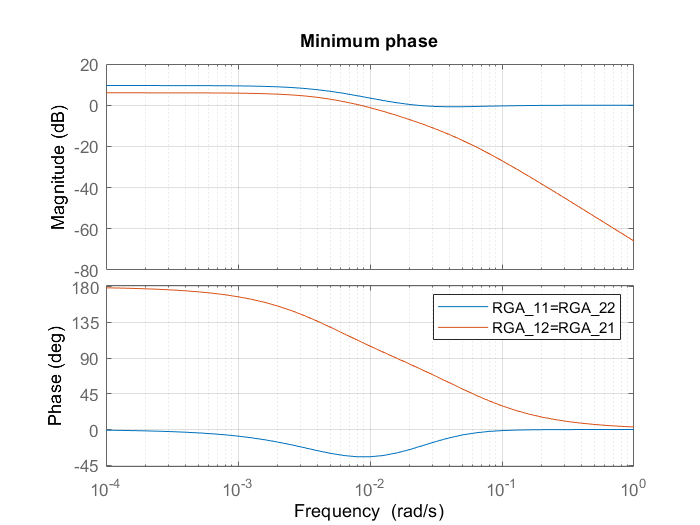

G_mp = tf(sys_mp);

omega = logspace(-4,2,61);
% RGA
for i = 1:length(omega)
    Gf = freqresp(G_mp,omega(i));
    RGA_w(:,:,i) = Gf.*inv(Gf).';
end
RGA = frd(RGA_w,omega);
bode(RGA(1,1),RGA(1,2),{1e-4, 1})
% bode(RGA)
title('Minimum phase')
legend('RGA_11=RGA_22', 'RGA_12=RGA_21')
grid on

%Non mimimum phase
run("quadtank_nonminphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          6.79      dx:     -2.95e-09 (0)
(2.) nlQuadtank/h2_state
      x:          8.78      dx:     -1.09e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.97      dx:      5.05e-09 (0)
(4.) nlQuadtank/h4_state1
      x:          4.17      dx:       1.3e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

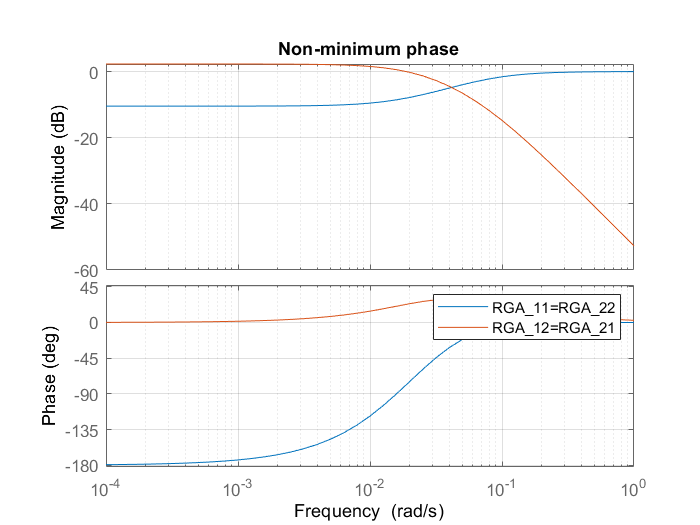

G_np = tf(sys_np);

omega = logspace(-4,2,61);
% RGA
for i = 1:length(omega)
    Gf = freqresp(G_np,omega(i));
    RGA_w(:,:,i) = Gf.*inv(Gf).';
end
RGA = frd(RGA_w,omega);
bode(RGA(1,1),RGA(1,2),{1e-4, 1})
% bode(RGA)
title('Non-minimum phase')
legend('RGA_11=RGA_22', 'RGA_12=RGA_21')
grid on